# Roberts operator

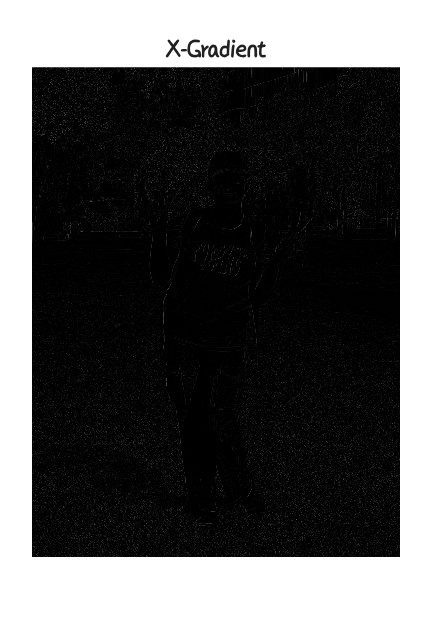


aa=rgb2gray(imread('DK.jpg'));
a=double(aa);
[row col]=size(a);

% Roberts Masks
w1=[1 0; 0 -1];
w2=[0 1; -1 0];

for x=1:row-1
    for y=1:col-1
        % Calculation for 2x2 mask
        a1(x,y)=w1(1)*a(x,y)+w1(2)*a(x,y+1)+w1(3)*a(x+1,y)+w1(4)*a(x+1,y+1);
        a2(x,y)=w2(1)*a(x,y)+w2(2)*a(x,y+1)+w2(3)*a(x+1,y)+w2(4)*a(x+1,y+1);
    end
end

a3=a1+a2; %% Final Gradient Image %%

figure(1)
imshow(uint8(a1)) %% The x-gradient image
title('X-Gradient')
exportgraphics(gcf, 'R1.png', 'Resolution', 300)


figure(2)
imshow(uint8(a2)) %% The y-gradient image
title('Y-Gradient')
exportgraphics(gcf, 'R2.png', 'Resolution', 300)


figure(3)
imshow(uint8(a3)) %% Final image %%
title('Final image')
exportgraphics(gcf, 'R3.png', 'Resolution', 300)